
% microtubule distribution calculations here

% file variables:
 
%%%%%%%%%%%%%%%%%%%%%%%%
% Isabel long mt fresh %
%%%%%%%%%%%%%%%%%%%%%%%%
file_numbers = 0:5

file_numbers =      0     1     2     3     4     5



filepath = 'Z:\Katia\2023_06_02\Microtuboles_with_labeled_and_az_2.5_and_2.5_percernt\Pos0\';
filepath2 = 'Z:\Katia\2023_06_02\Microtuboles_with_labeled_and_az_2.5_and_2.5_percernt\JPEG_folder\';

filename = strcat('img_00000000',int2str(2),'_Default_000')

filename = 'img_000000002_Default_000'

dest_path = 'C:\Users\kathe\Desktop\DogicLab\4_8_2023\'

dest_path = 'C:\Users\kathe\Desktop\DogicLab\4_8_2023\'

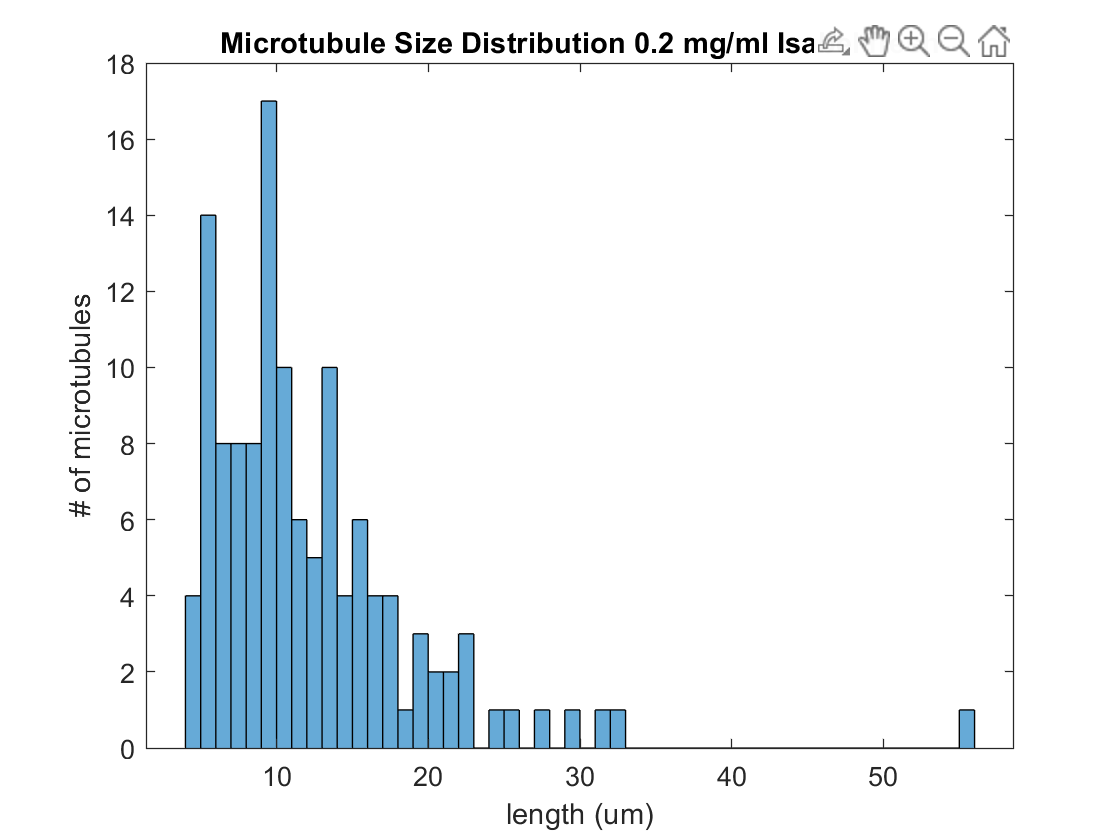

L0 = imread(strcat(filepath,filename,'.tif'));
L_PNG = imread(strcat(filepath2, filename,'.jpg'));
figure;
L0 = L0 > 800;
statsL0 = regionprops('table',L0,'Centroid','MajorAxisLength');
centersL0 = statsL0.Centroid; diametersL0 = statsL0.MajorAxisLength;
diametersL0 = statsL0.MajorAxisLength; 
min_diameter_L0 = diametersL0 > 13; % image specific minimum diameter to eliminate dust/noise

diameters_cut_L0 = diametersL0(min_diameter_L0);
centers_cut_L0 = centersL0(min_diameter_L0,:);

%show the figure
%figure; imshow(L_PNG); title('cut noise'); hold on; viscircles(centers_cut_L0,diameters_cut_L0/2); hold off;
diameters_IF = [diameters_cut_L0;]; %;diametersL1(diameters_cropL1);...
figure;

% plot the historgram
h = histogram((diameters_IF)*0.3667,'BinWidth',1.0); % 0.3667 micron per pix, photometrics 2x2 60x
title("Microtubule Size Distribution 0.2 mg/ml Isabel fresh");
xlabel('length (um)');
ylabel('# of microtubules');
%save histogram to destination path
saveas(h, strcat('hist_',filename), 'jpeg')


% topDir ='./';
% imDir_name = 'binaries\'; 
% realOverlay_dir = 'jpegs\';
% micron_per_pixel = 0.2167; % 0.2167 micron per pix, andor zyla 5.5 2x2 60x
% 
% imDir = [topDir, imDir_name];
% realImDir = [topDir, realOverlay_dir];
% 
% %make the directories
% mkdir(topDir,'measurement_overlays');
% mkdir(topDir,'measurement_real_overlays');
% mkdir(topDir,'mt_lengths_microns');
% 
% % Count the number of frames
% imfiles = dir([imDir,'*.tif'])
% fprintf(imfiles)
% realImfiles = dir([realImDir,'*.jpg']);
% 
% NFrames = length(imfiles); % add mismatch error output here
% 
% all_diameters = [];
% plotstatus=0; 
% for i=1:NFrames % can change which images to run through
%     %disp(['computing director field on frame ', int2str(i)]);
%     realIm = imread([realImDir, realImfiles(i).name]);
%     im = imread([imDir, imfiles(i).name]);
%     im = imcomplement(im);
%     im = im > 0;
%     
%     % figure;imshow(im);title('bw'); %% debug
% 
%     stats_im = regionprops('table',im,'Centroid','MajorAxisLength');
%     centers_im = stats_im.Centroid; diameters_im = stats_im.MajorAxisLength;
%     %figure; imshow(im); title('vis circles'); hold on; viscircles(centers_im,diameters_im/2); hold off;
%     
%     min_diameter = diameters_im > 2.38/micron_per_pixel; % pixel minimum diameter to eliminate dust/noise, currently using pixel equiv of 2.38 micron for all long mt data, 3*that for really clumpy
%     diameters_cut = diameters_im(min_diameter);
%     centers_cut = centers_im(min_diameter,:);
% 
%     figure("Visible","off"); imshow(im); title(strcat('binary cut noise ', imfiles(i).name ) ); hold on; viscircles(centers_cut,diameters_cut/2); hold off;
%     saveas(gcf, [topDir, 'measurement_overlays\', sprintf('%05d', i), '.tif']);
%     
%     figure("Visible","off"); imshow(realIm); title(strcat('real cut noise ', realImfiles(i).name)); hold on; viscircles(centers_cut,diameters_cut/2); hold off;
%     saveas(gcf, [topDir, 'measurement_real_overlays\', sprintf('%05d', i), '.tif']);
%     
%     close all % closes figures to prevent memory issues
%     
%     diameters_microns = diameters_cut*micron_per_pixel;
%     save([topDir, 'mt_lengths_microns\', num2str(i, '%04.f'), '.mat'], 'diameters_microns')
%     
%     all_diameters = [all_diameters; diameters_microns];
% 
%     %directorField = [xin yin nxin nyin];
%   
%  
%     %%save([topDir, 'director_allFrames/director_', num2str(i, '%04.f'), '.mat'], 'directorField')   
%     %save([imDir_name,'Directors/director_', num2str(i, '%04.f'), '.mat'],'directorField')
% end

% figure;
% histogram(all_diameters,'BinWidth',1.0, 'Normalization','probability');
% title("Microtubule Size Distribution 0.2 mg/ml");
% xlabel('length (um)');
% ylabel('Probability');
% %ylim([0 0.1])
% %xlim([0 70])
% 
% mean_dia = mean(all_diameters);
% std_dia = std(all_diameters);
% len = length(all_diameters);
% 
% % text box
% dim = [0.5 0.5 0.3 0.3];
% str = {strcat('mean = ',num2str(mean_dia) ),strcat('std dev = ',num2str(std_dia)),...
%     strcat('Total num microtubules = ', num2str(len))};
% annotation('textbox',dim,'String',str,'FitBoxToText','on');
% 
% %saveas(gcf, [topDir, 'length_distribution_hist_normalized.png']);

% figure;
% histogram(all_diameters,'BinWidth',1.0);
% title("Microtubule Size Distribution 0.2 mg/ml");
% xlabel('length (um)');
% ylabel('# of microtubules');
% %ylim([0 70])
% %xlim([0 70])
% 
% % text box
% dim = [0.5 0.5 0.3 0.3];
% str = {strcat('mean = ',num2str(mean_dia) ),strcat('std dev = ',num2str(std_dia)),...
%     strcat('Total num microtubules = ', num2str(len))};
% annotation('textbox',dim,'String',str,'FitBoxToText','on');
% 
% saveas(gcf, [topDir, 'length_distribution_hist.png']);